## 任务：

分别用欧拉法和四阶龙格-库塔法求微分方程的数值解，并与解析解  $y(t)=\frac{1}{3}e^{-30t}$比较. $\dot y(t)=-30y(t),y(0)=\frac{1}{3}$ , 0≤t≤1.5s, h=0.1,0.075,0.05

### 欧拉法

对于一阶微分方程初值问题$\dot{\;y} =f\left(t,y\right),y\left(t_0 \right)=y_0$

使用下述迭代计算式来代替原始的欧拉方程：$y_{k+1} =y_k +h\cdot f\left(x_k ,y_k \right)$

显然这里的$f\left(t,y\right)=-30y$

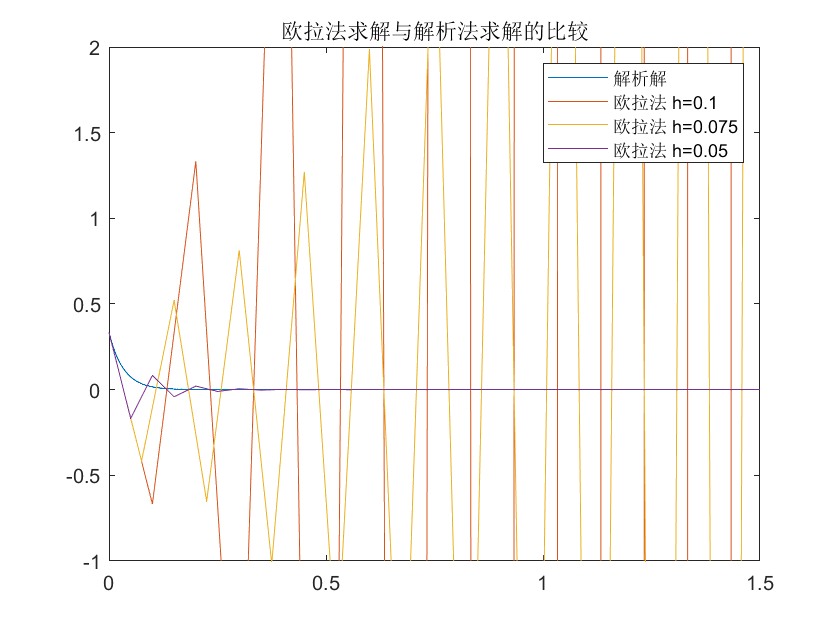

h=[0.1;0.075;0.05];
y0=1/3;
x=0:0.0001:1.5; % 绘图横轴
y_real=1/3*exp(-30*(0:0.0001:1.5)); % 解析解
plot(x,y_real);hold on;
for i=1:length(h)
    clear t y_euler;
    t=0:h(i,1):1.5;
    y_euler(1,1)=y0;
    for tk=1:length(t)
        y_euler(1,tk+1)=y_euler(1,tk)...
            +h(i,1)*(-30*y_euler(1,tk));
    end
    plot(t,y_euler(:,1:length(t)));hold on;
end
hold off;ylim([-1 2]);
title('欧拉法求解与解析法求解的比较');
legend('解析解','欧拉法 h=0.1',...
    '欧拉法 h=0.075','欧拉法 h=0.05');

### 四阶龙格-库塔法

对于一阶微分方程初值问题$\dot{\;y} =f\left(t,y\right),y\left(t_0 \right)=y_0$中，四阶龙格库塔求解算法为：


$$\begin{cases}
k_1=f(t(k),y(k))\\
k_2=f(t(k)+\frac{h}{2},y(k)+\frac{h}{2}k_1)\\
k_3=f(t(k)+\frac{h}{2},y(k)+\frac{h}{2}k_2)\\
k_4=f(t(k)+h,y(k)+hk_3)\\
y(k+1)=y(k)+\frac{h}{6}(k_1+2k_2+2k_3+k_4)\\
y(0)=y_0
\end{cases}$$


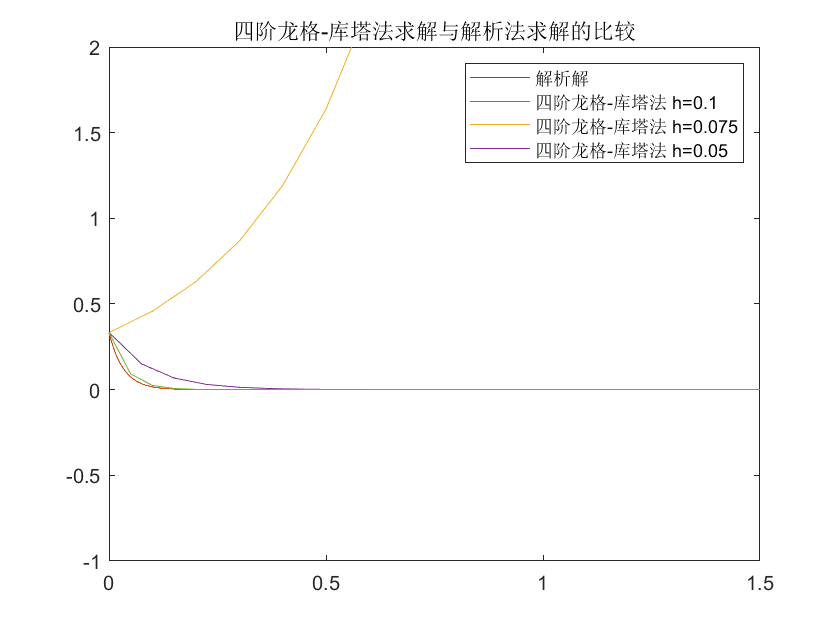

h=[0.1;0.075;0.05];
y0=1/3;
x=0:0.0001:1.5; % 绘图横轴
y_real=1/3*exp(-30*(0:0.0001:1.5)); % 解析解
plot(x,y_real);hold on;
for i=1:length(h)
    clear t y_rk k1 k2 k3 k4;
    t=0:h(i,1):1.5;
    y_rk(1,1)=y0;
    for tk=1:length(t)
        k1=-30*y_rk(1,tk);
        k2=-30*(y_rk(1,tk)+h(i,1)/2*k1);
        k3=-30*(y_rk(1,tk)+h(i,1)/2*k2);
        k4=-30*(y_rk(1,tk)+h(i,1)*k3);
        y_rk(1,tk+1)=y_rk(1,tk)...
            +h(i,1)/6*(k1+2*k2+2*k3+k4);
    end
    plot(t,y_rk(:,1:length(t)));hold on;
end
hold off;ylim([-1 2]);
title('四阶龙格-库塔法求解与解析法求解的比较');
legend('解析解','四阶龙格-库塔法 h=0.1',...
    '四阶龙格-库塔法 h=0.075',...
    '四阶龙格-库塔法 h=0.05');